# **Joe Zhang - Crater Dune Field Analysis (04/22/17)**

## **Introduction**

In this LiveScript, I analyze HiRISE DTM data for my FRS124 writing assignment.

## Section 1: Downloads the DTM files

% directory where DTM files are located
diro='/Users/zhaozhang/frs124/W01';

% 20km crater in Meridiani Planum exposing layers
fid1=fopen(fullfile(diro,'DTEED_029804_1770_029092_1770_A01.IMG'));
dtm1=fread(fid1,'float');

% Dunes and slopes in crater southwest of Xainza Crater
fid2=fopen(fullfile(diro,'DTEEC_043742_1800_043597_1800_A01.IMG'));
dtm2=fread(fid2,'float');

% Herschel Crater dunes change detection
fid3=fopen(fullfile(diro,'DTEEC_037948_1645_038291_1645_A01.IMG'));
dtm3=fread(fid3,'float');

% Dark dunes in Herschel Crater
fid4=fopen(fullfile(diro,'DTEEC_002860_1650_003572_1650_U01.IMG'));
dtm4=fread(fid4,'float');

% Topography of moving dunes in Nili Patera
fid5=fopen(fullfile(diro,'DTEEC_017762_1890_018039_1890_A01.IMG'));
dtm5=fread(fid5,'float');

% Dune changes west of Meroe Patera
fid6=fopen(fullfile(diro,'DTEEC_038214_1875_038280_1875_A01.IMG'));
dtm6=fread(fid6,'float');


## Section 2: Plots the elevation data and removes no data areas

% finds the true elevation range from the header file
elevmin1 = -3005.07; elevmax1 = -1138.63; clims1 = [elevmin1 elevmax1];
elevmin2 = -2175.45; elevmax2 = -1338.00; clims2 = [elevmin2 elevmax2];
elevmin3 =  1235.29; elevmax3 =  1474.56; clims3 = [elevmin3 elevmax3];
elevmin4 =  1144.10; elevmax4 =  1232.60; clims4 = [elevmin4 elevmax4];
elevmin5 =    55.11; elevmax5 =   275.45; clims5 = [elevmin5 elevmax5];
elevmin6 =   381.09; elevmax6 =   812.98; clims6 = [elevmin6 elevmax6];

% removes the no data areas
dtm1(dtm1>=elevmax1)=NaN; dtm1(dtm1<=elevmin1)=NaN; 
dtm2(dtm2>=elevmax2)=NaN; dtm2(dtm2<=elevmin2)=NaN; 
dtm3(dtm3>=elevmax3)=NaN; dtm3(dtm3<=elevmin3)=NaN;
dtm4(dtm4>=elevmax4)=NaN; dtm4(dtm4<=elevmin4)=NaN;
dtm5(dtm5>=elevmax5)=NaN; dtm5(dtm5<=elevmin5)=NaN;
dtm6(dtm6>=elevmax6)=NaN; dtm6(dtm6<=elevmin6)=NaN;


## Section 3: Reshapes the vector into a matrix for display

% reshapes the vector into a matrix so that it will display as an image
lines1 = 13314; samples1 = 3717;
dtm1s=reshape(dtm1(end-samples1*lines1+1:end),samples1,lines1)';
lines2 = 11896; samples2 = 6049;
dtm2s=reshape(dtm2(end-samples2*lines2+1:end),samples2,lines2)';
lines3 = 20721; samples3 = 6930;
dtm3s=reshape(dtm3(end-samples3*lines3+1:end),samples3,lines3)';
lines4 = 15763; samples4 = 7070;
dtm4s=reshape(dtm4(end-samples4*lines4+1:end),samples4,lines4)';
lines5 = 15282; samples5 = 7035;
dtm5s=reshape(dtm5(end-samples5*lines5+1:end),samples5,lines5)';
lines6 = 13278; samples6 = 6303;
dtm6s=reshape(dtm6(end-samples6*lines6+1:end),samples6,lines6)';

## Section 4: Plots for the appendix with identified regions of interest

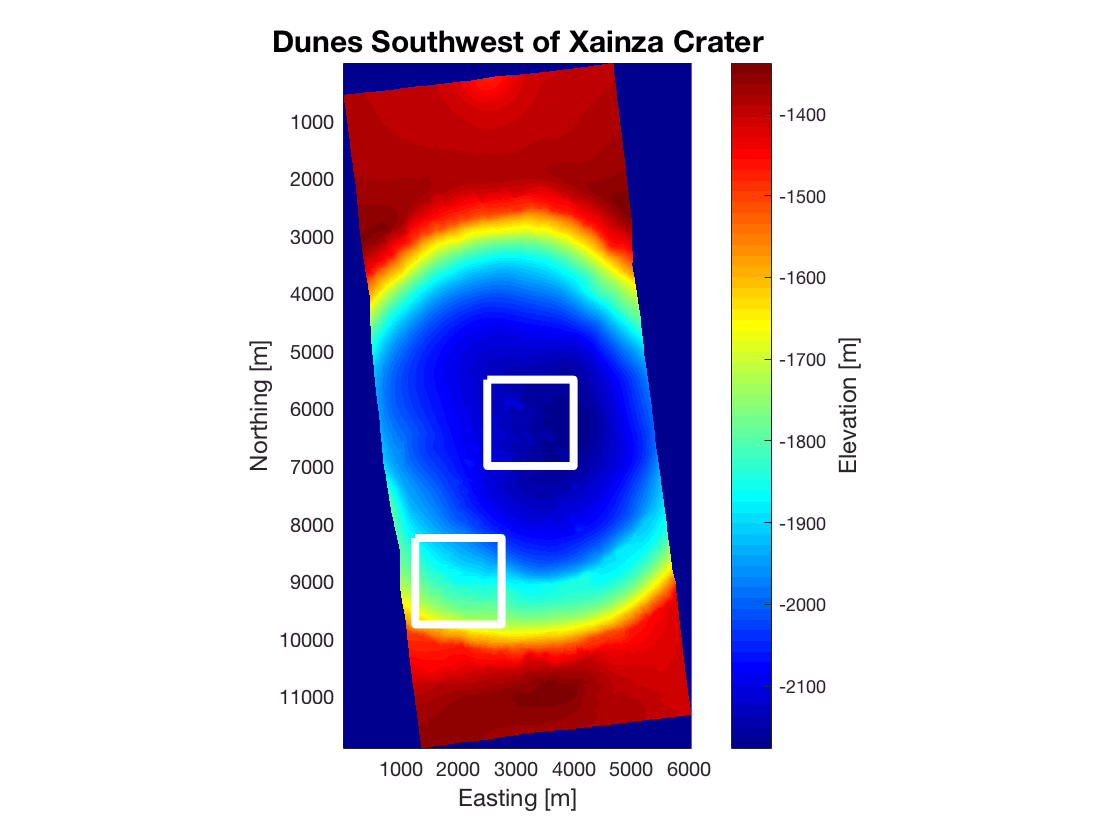

% plots the elevation data
%row (y) and column (x) cropping instructions for the two areas of interest
% region 1
cy1=5500; cy2=7000;
cx1=2500; cx2=4000;
% region 2
cy3=8250; cy4=9750;
cx3=1250; cx4=2750;
figure (1)
clf
hold on
imagesc(dtm2s,clims2)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
xlabel('Easting [m]','FontSize',12);
ylabel('Northing [m]','FontSize',12);
ylabel(c,'Elevation [m]','FontSize',12);
plot([cx1 cx2 cx2 cx1 cx1],[cy1 cy1 cy2 cy2 cy1],'-w','LineWidth',4)
plot([cx3 cx4 cx4 cx3 cx3],[cy3 cy3 cy4 cy4 cy3],'-w','LineWidth',4)
title('Dunes Southwest of Xainza Crater','FontSize',15);
hold off
figdir='/Users/zhaozhang/frs124/W01';
% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'dtm2-fig.pdf'))

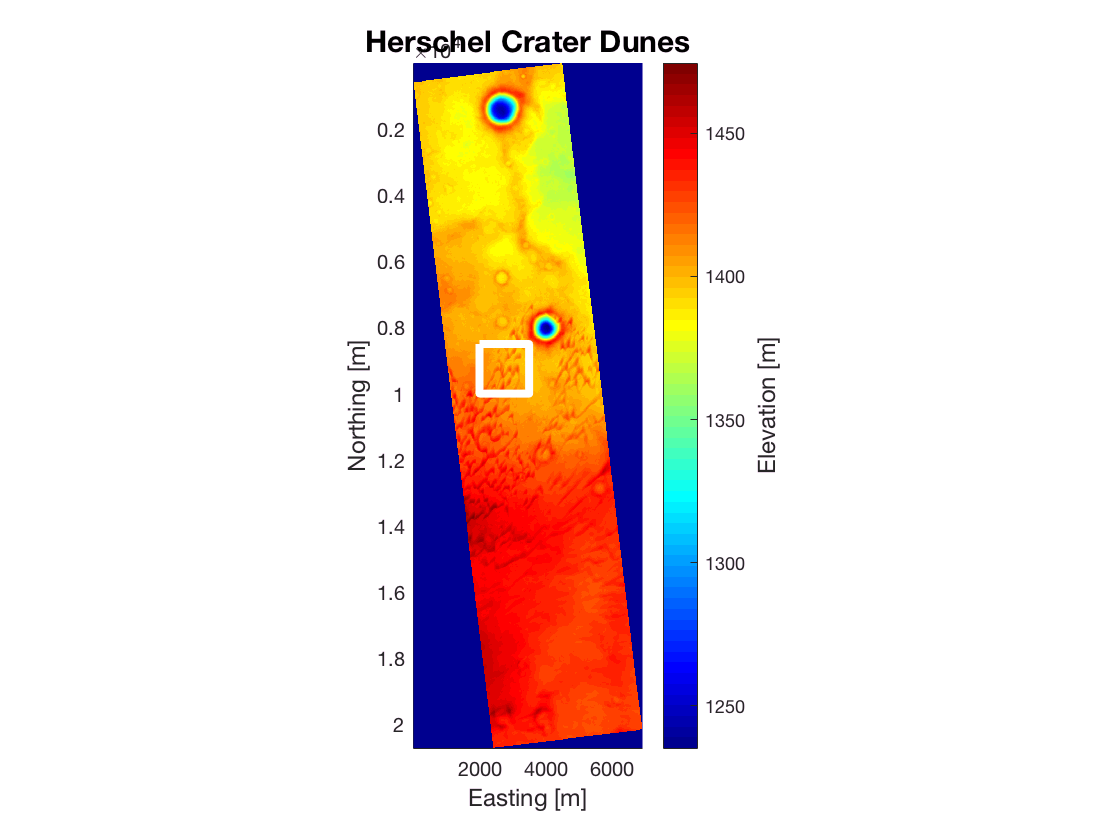

% plots the elevation data
%row (y) and column (x) cropping instructions for the two areas of interest
% region 1
cy5=8500; cy6=10000;
cx5=2000; cx6=3500;
figure (2)
clf
hold on
imagesc(dtm3s,clims3)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
xlabel('Easting [m]','FontSize',12);
ylabel('Northing [m]','FontSize',12);
ylabel(c,'Elevation [m]','FontSize',12);
plot([cx5 cx6 cx6 cx5 cx5],[cy5 cy5 cy6 cy6 cy5],'-w','LineWidth',4)
title('Herschel Crater Dunes','FontSize',15);
hold off
figdir='/Users/zhaozhang/frs124/W01';
% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'dtm3-fig.pdf'))

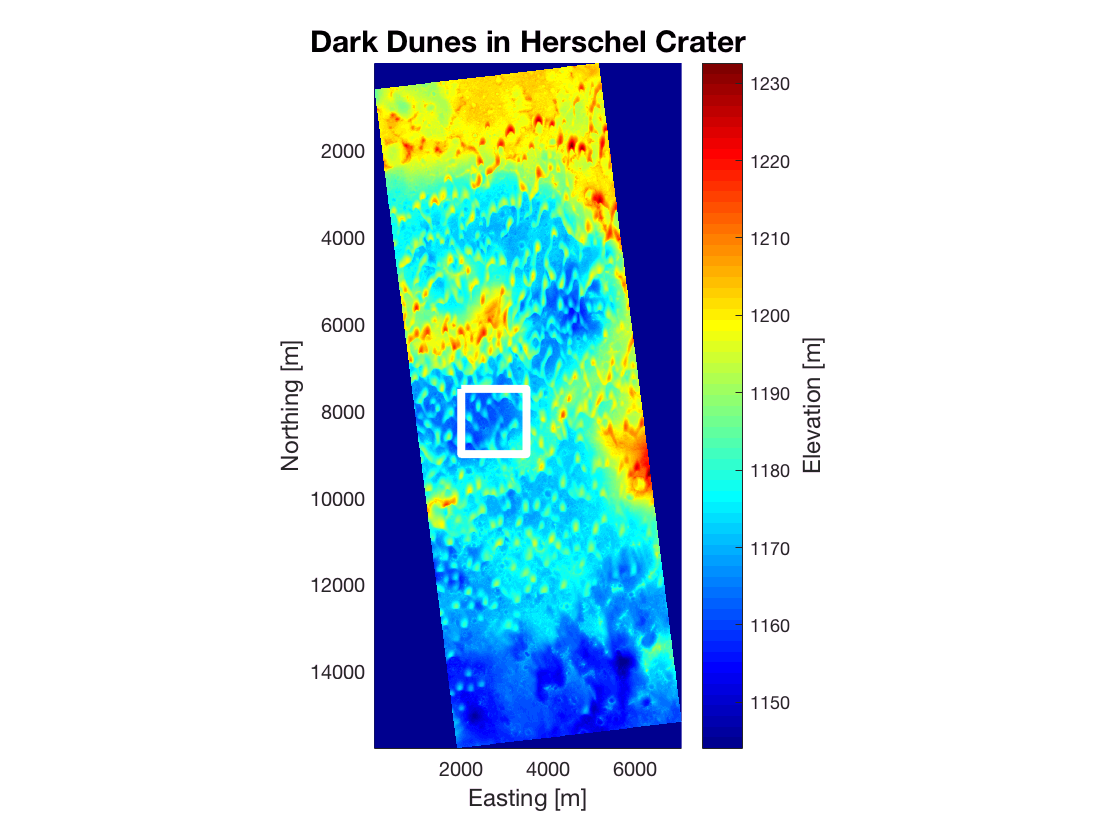

% plots the elevation data
%row (y) and column (x) cropping instructions for the two areas of interest
% region 1
cy9=7500; cy10=9000;
cx9=2000; cx10=3500;
figure (3)
clf
hold on
imagesc(dtm4s,clims4)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
xlabel('Easting [m]','FontSize',12);
ylabel('Northing [m]','FontSize',12);
ylabel(c,'Elevation [m]','FontSize',12);
plot([cx9 cx10 cx10 cx9 cx9],[cy9 cy9 cy10 cy10 cy9],'-w','LineWidth',4)
title('Dark Dunes in Herschel Crater','FontSize',15);
hold off
figdir='/Users/zhaozhang/frs124/W01';

% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'dtm4-fig.pdf'))

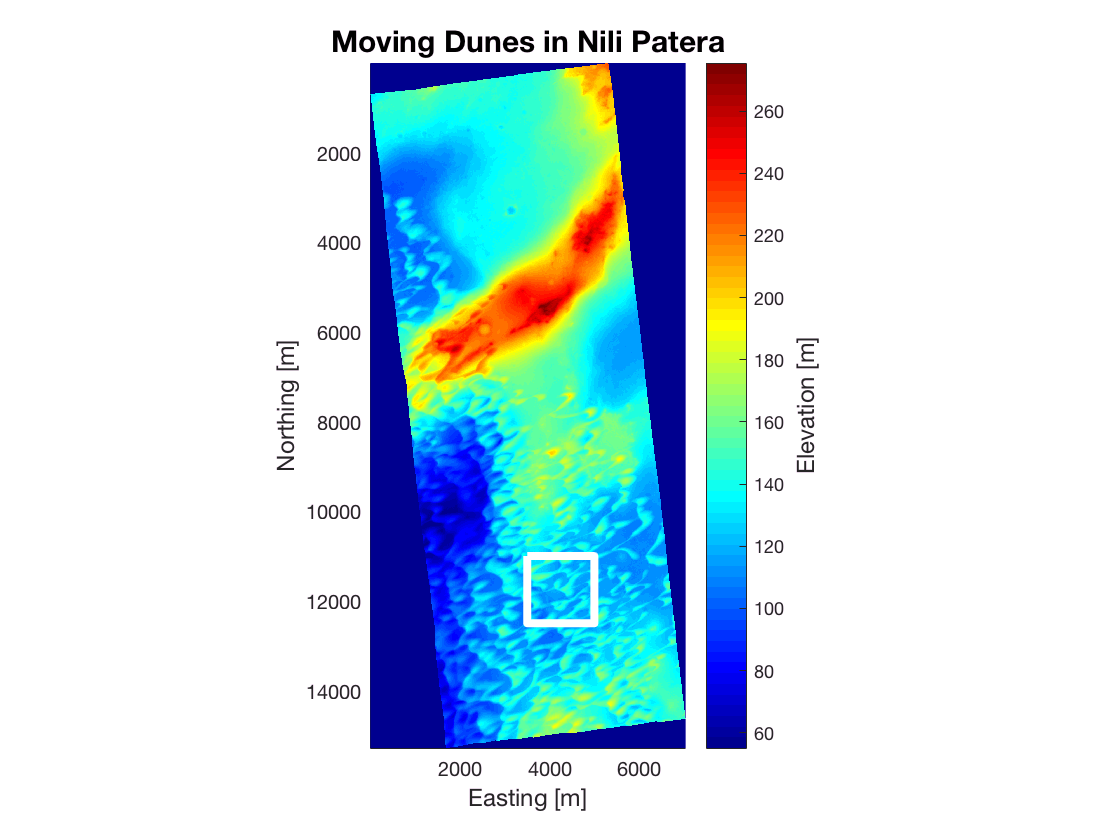

% plots the elevation data
%row (y) and column (x) cropping instructions for the two areas of interest
% region 1
cy13=11000; cy14=12500;
cx13=3500; cx14=5000;
figure (4)
clf
hold on
imagesc(dtm5s,clims5)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
xlabel('Easting [m]','FontSize',12);
ylabel('Northing [m]','FontSize',12);
ylabel(c,'Elevation [m]','FontSize',12);
plot([cx13 cx14 cx14 cx13 cx13],[cy13 cy13 cy14 cy14 cy13],'-w','LineWidth',4)
title('Moving Dunes in Nili Patera','FontSize',15);
hold off
figdir='/Users/zhaozhang/frs124/W01';
% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'dtm5-fig.pdf'))

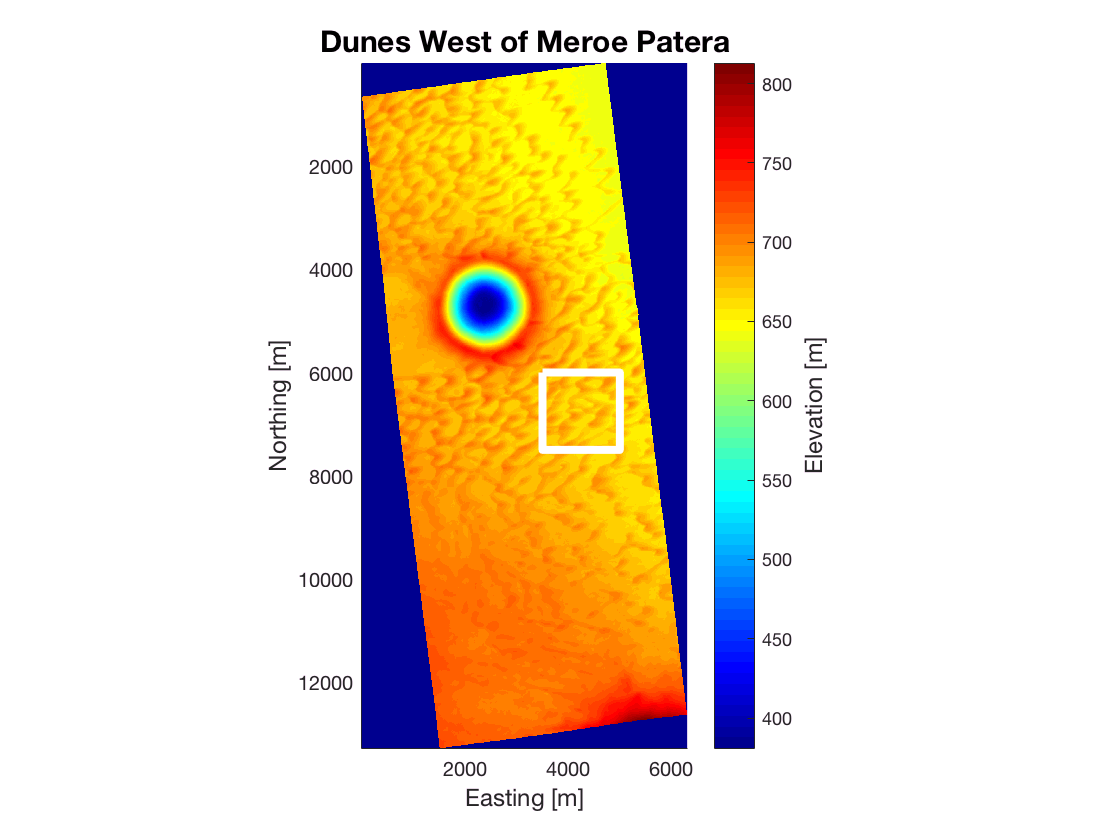

% plots the elevation data
%row (y) and column (x) cropping instructions for the two areas of interest
% region 1
cy17=6000; cy18=7500;
cx17=3500; cx18=5000;
figure (5)
clf
hold on
imagesc(dtm6s,clims6)
colormap jet
axis image
c=colorbar;
set(gca,'ydir','rev');
xlabel('Easting [m]','FontSize',12);
ylabel('Northing [m]','FontSize',12);
ylabel(c,'Elevation [m]','FontSize',12);
plot([cx17 cx18 cx18 cx17 cx17],[cy17 cy17 cy18 cy18 cy17],'-w','LineWidth',4)
title('Dunes West of Meroe Patera','FontSize',15);
hold off
figdir='/Users/zhaozhang/frs124/W01';
% Issue the print command, which does the same as "save" it
print('-dpdf',fullfile(figdir,'dtm6-fig.pdf'))